## **Load Thermal and Geometric parameters**

OBJ_params = bh_sys_params_CLS("bh_PARAMS_DATABASE.xlsx", "SET_1");

Set the Finite Difference interval widths $\Delta x$ and $\Delta y$ 

OBJ_params = OBJ_params.set_deltas(1e-3, 1e-3)

OBJ_params =   bh_sys_params_CLS with properties:

     Filename: "bh_PARAMS_DATABASE.xlsx"
    Sheetname: "SET_1"
       my_tab: [19×5 table]
          k_A: 0.1700
          k_B: 0.1200
          k_C: 0.0488
       h_ROOF: 4
       h_CEIL: 1.3000
       T_ROOF: 55
       T_CEIL: 25
          xLA: 0.3000
          xLB: 0.0175
          xLC: 0.2825
          yLA: 0.0130
          yLB: 0.0900
          yLC: 0.1950
         Nx_A: 300
         Nx_B: 18
         Nx_C: 282
         Ny_A: 13
         Ny_B: 90
         Ny_C: 195
      Delta_X: 1.0000e-03
      Delta_Y: 1.0000e-03


## Compute the Finite Diference STENCILS for the different NODE types

OBJ_fd_stencils = bh_fd_stencil_CLS(OBJ_params)

OBJ_fd_stencils =   bh_fd_stencil_CLS with properties:

    tab: [23×15 table]


Inspect one of the node stencils

OBJ_fd_stencils.show(bh_fd_node_type_ENUM.G_BLK_B_INTERNAL,"symbolic")


 ------------------------------ 
 *** SYMBOLIC *** A.x = b
 --->  x 

$$ans = \left(\begin{array}{ccccccccc} T_{\mathrm{mM1},\mathrm{nP1}} & T_{m,\mathrm{nP1}} & T_{\mathrm{mP1},\mathrm{nP1}} & T_{\mathrm{mM1},n} & T_{m,n} & T_{\mathrm{mP1},n} & T_{\mathrm{mM1},\mathrm{nM1}} & T_{m,\mathrm{nM1}} & T_{\mathrm{mP1},\mathrm{nM1}} \end{array}\right)$$


 --->  A 

$$ans = \left(\begin{array}{ccccccccc} 0 & -\frac{\Delta_{X}\,k_{B}}{\Delta_{Y}} & 0 & -\frac{\Delta_{Y}\,k_{B}}{\Delta_{X}} & \frac{2\,\Delta_{X}\,k_{B}}{\Delta_{Y}}+\frac{2\,\Delta_{Y}\,k_{B}}{\Delta_{X}} & -\frac{\Delta_{Y}\,k_{B}}{\Delta_{X}} & 0 & -\frac{\Delta_{X}\,k_{B}}{\Delta_{Y}} & 0 \end{array}\right)$$


 --->  b 

$$ans = \left(\begin{array}{c} 0 \end{array}\right)$$

The main data component for this is the table:

OBJ_fd_stencils.tab

ans = 23×15 table
                           node_type_fd          s_A          s_b          s_x                                                                  str_x                                                               T_mM1_nP1     T_m_nP1     T_mP1_nP1     T_mM1_n      T_m_n      T_mP1_n     T_mM1_nM1     T_m_nM1     T_mP1_nM1     b  
                        __________________    _________    _________    _________    ___________________________________________________________________________________________________________________________    _________    _________    _________    

## Create the Node Blocks

block_A = bh_block_CLS(OBJ_params.Nx_A, OBJ_params.Ny_A,"i_offset",0,"j_offset",0);
block_B = bh_block_CLS(OBJ_params.Nx_B, OBJ_params.Ny_B, ...
                       "i_offset",0, ...
                       "j_offset",OBJ_params.Ny_A);
block_C = bh_block_CLS(OBJ_params.Nx_C, OBJ_params.Ny_C, ...
                       "i_offset",OBJ_params.Nx_B, ...
                       "j_offset",OBJ_params.Ny_A);

And visualize the blocks

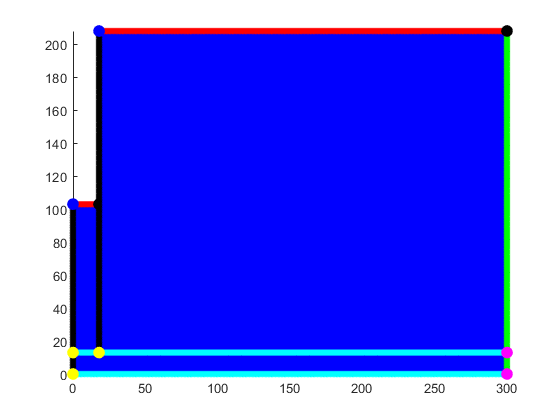

figure;
hax = axes();
block_A.plot("Global_ij", "Parent",hax)
block_B.plot("Global_ij", "Parent",hax)
block_C.plot("Global_ij", "Parent",hax)

## Join the blocks and configure the nodes

OBJ_fd_mesh = bh_fd_mesh_CLS(block_A, block_B, block_C)

OBJ_fd_mesh =   bh_fd_mesh_CLS with properties:

       tab: [61019×8 table]
    T_list: [61019×1 string]
     A_sys: []
     b_sys: []
     x_sys: []


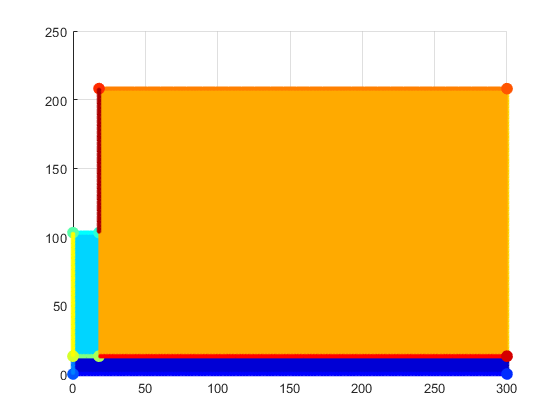


OBJ_fd_mesh.plot()

The main data component for this is the table:

head(OBJ_fd_mesh.tab)

ans = 8×8 table
                i_local    j_local    i_global    j_global    is_active    node_type_blk       node_type_fd       NODE_NAME 
                _______    _______    ________    ________    _________    _____________    __________________    __________

    NODE_1_1       1          1          1           1          true        "INTERNAL"      "G_BLK_A_INTERNAL"    "NODE_1_1"
    NODE_2_1       2          1          2           1          true        "INTERNAL"      "G_BLK_A_INTERNAL"    "NODE_2_1"
    NODE_3_1       3          1          3           1          true        "INTERNAL"      "G_BLK_A_INTERNAL"    "NODE_3_1"
    NODE_4_1      

## Assemble the system A.x=b equations

OBJ_fd_mesh = OBJ_fd_mesh.assemble_sys_A_b(OBJ_fd_stencils)


 ... completed kk= 1000
 ... completed kk= 2000
 ... completed kk= 3000
 ... completed kk= 4000
 ... completed kk= 5000
 ... completed kk= 6000
 ... completed kk= 7000
 ... completed kk= 8000
 ... completed kk= 9000
 ... completed kk=10000
 ... completed kk=11000
 ... completed kk=12000
 ... completed kk=13000
 ... completed kk=14000
 ... completed kk=15000
 ... completed kk=16000
 ... completed kk=17000
 ... completed kk=18000
 ... completed kk=19000
 ... completed kk=20000
 ... completed kk=21000
 ... completed kk=22000
 ... completed kk=23000
 ... completed kk=24000
 ... completed kk=25000
 ... completed kk=26000
 ... completed kk=27000
 ... completed kk=28000
 ... completed kk=29000
 ... completed kk=30000
 ... completed kk=31000
 ... completed kk=32000
 ... completed kk=33000
 ... completed kk=34000
 ... completed kk=35000
 ... completed kk=36000
 ... completed kk=37000
 ... completed kk=38000
 ... completed kk=39000
 ... completed kk=40000
 ... completed kk=41000
 ... completed 

OBJ_fd_mesh =   bh_fd_mesh_CLS with properties:

       tab: [61019×8 table]
    T_list: [61019×1 string]
     A_sys: [61019×61019 double]
     b_sys: [61019×1 double]
     x_sys: []


## And solve the system

OBJ_fd_mesh = OBJ_fd_mesh.solve();

[T_col, mn_mat] = OBJ_fd_mesh.results_retrieve();

## And Visualize the results

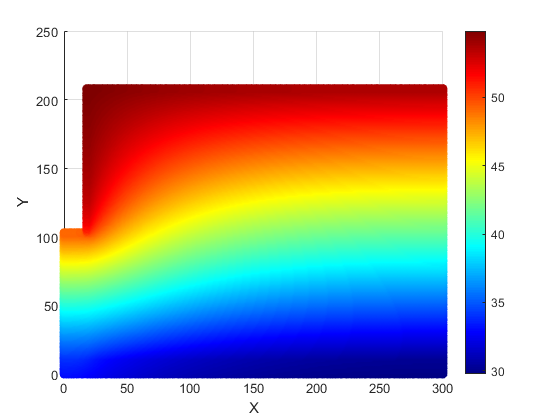

OBJ_fd_mesh.results_plot("scatter");